## Análisis cinemático

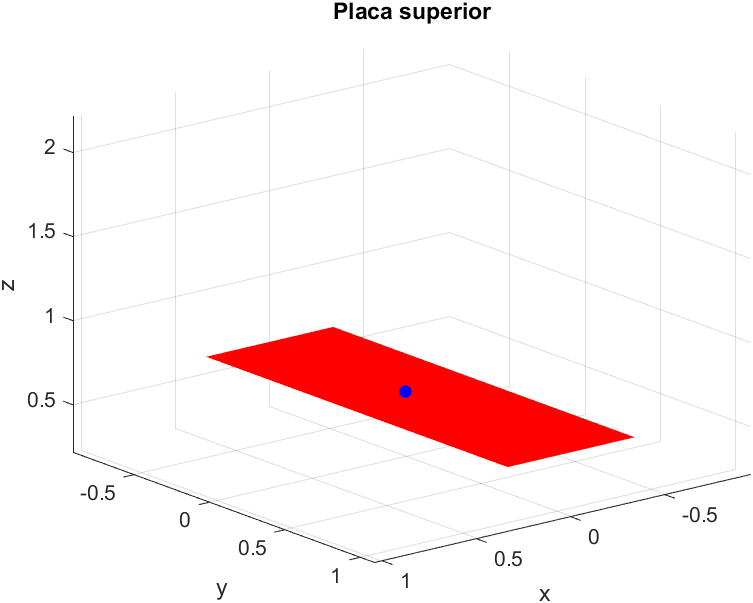

b=2.365;
h=0.57;

syms Fbeta(t) Ftheta(t) x y z x_x(t) x_z(t)

Pi=[x y z];

Balanceo

syms omega_b(t) alpha_b(t) tMax_b
tMax_b=0.5

tMax_b = 0.5000

alpha_b(t)=-5

$$alpha\_b(t) = -5$$


omega_b(t)=int(alpha_b(t),t);
Cb1=-omega_b(tMax_b);
omega_b(t)=omega_b+Cb1

$$omega\_b(t) = \frac{5}{2}-5\,t$$

Fbeta(t)=int(omega_b);
Cb2=-18*pi/180;
Fbeta(t)=Fbeta(t)+Cb2

$$Fbeta(t) = -\frac{\pi }{10}-\frac{5\,t\,\left(t-1\right)}{2}$$

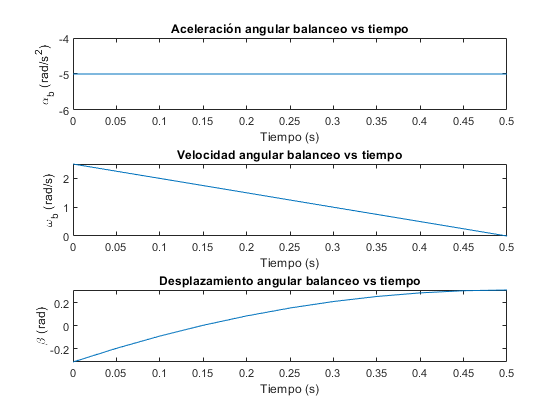


tiempo=0:0.05:0.5;
subplot(3,1,1)
plot(tiempo,alpha_b(tiempo))
title('Aceleración angular balanceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\alpha_b (rad/s^2)')
subplot(3,1,2)
plot(tiempo,omega_b(tiempo))
title('Velocidad angular balanceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\omega_b (rad/s)')
subplot(3,1,3)
plot(tiempo,Fbeta(tiempo))
title('Desplazamiento angular balanceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\beta (rad)')

syms omega_c(t) alpha_c(t) TMax_c
tMax_c=0.4

tMax_c = 0.4000

alpha_c(t)=-6.55

$$alpha\_c(t) = -\frac{131}{20}$$


omega_c(t)=int(alpha_c(t),t);
Cc1=-omega_c(tMax_c);
omega_c(t)=omega_c+Cc1

$$omega\_c(t) = \frac{131}{50}-\frac{131\,t}{20}$$

Ftheta_c(t)=int(omega_c);
Cb2=-15*pi/180;
Ftheta_c(t)=Ftheta_c(t)+Cb2

$$Ftheta\_c(t) = -\frac{\pi }{12}-\frac{131\,t\,\left(5\,t-4\right)}{200}$$


tiempo=0:0.05:0.4

tiempo =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000


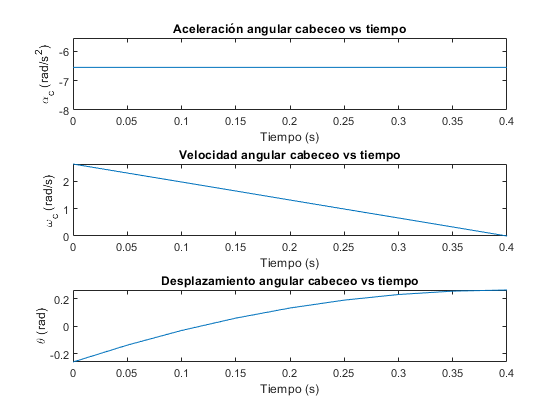

subplot(3,1,1)
plot(tiempo,alpha_c(tiempo))
title('Aceleración angular cabeceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\alpha_c (rad/s^2)')
subplot(3,1,2)
plot(tiempo,omega_c(tiempo))
title('Velocidad angular cabeceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\omega_c (rad/s)')
subplot(3,1,3)
plot(tiempo,Ftheta_c(tiempo))
title('Desplazamiento angular cabeceo vs tiempo')
xlabel('Tiempo (s)')
ylabel('\theta (rad)')

### Ecuaciones generales


Wbeta(t)=[Fbeta(t) 0 0];
Wtheta(t)=[0 Ftheta_c(t) 0];
Wtotal(t)=diff(Wbeta(t)+Wtheta(t));

VelocidadPO(t)=cross(Wtotal(t),Pi);
aceleracionAngular(t)=diff(Wtotal(t));

AceleracionPO(t)=cross(aceleracionAngular(t),Pi)+cross(Wtotal(t),VelocidadPO(t));


Velocidad=formula(VelocidadPO(t)+diff([x_x(t) 0 x_z(t)]));
Vx=Velocidad(1)

$$Vx = \frac{\partial }{\partial t}x_{x}\left(t\right)-z\,\left(\frac{131\,t}{20}-\frac{131}{50}\right)$$

Vy=Velocidad(2)

$$Vy = z\,\left(5\,t-\frac{5}{2}\right)$$

Vz=Velocidad(3)

$$Vz = \frac{\partial }{\partial t}x_{z}\left(t\right)+x\,\left(\frac{131\,t}{20}-\frac{131}{50}\right)-y\,\left(5\,t-\frac{5}{2}\right)$$


Aceleracion=formula(AceleracionPO(t)+diff(diff([x_x(t) 0 x_z(t)])))

$$Aceleracion = \begin{array}{l} \left(\begin{array}{ccc} \frac{\partial^{2}}{\partial t^{2}}x_{x}\left(t\right)-\frac{131\,z}{20}-\sigma_{2}\,\sigma_{1} & 5\,z+\left(5\,t-\frac{5}{2}\right)\,\sigma_{1} & \frac{131\,x}{20}-5\,y-z\,{\left(5\,t-\frac{5}{2}\right)}^{2}-z\,{\sigma_{2}}^{2}+\frac{\partial^{2}}{\partial t^{2}}x_{z}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x\,\sigma_{2}-y\,\left(5\,t-\frac{5}{2}\right)\\ \sigma_{2}=\frac{131\,t}{20}-\frac{131}{50} \end{array}$$

Ax=Aceleracion(1)

$$Ax = \frac{\partial^{2}}{\partial t^{2}}x_{x}\left(t\right)-\frac{131\,z}{20}-\left(\frac{131\,t}{20}-\frac{131}{50}\right)\,\left(x\,\left(\frac{131\,t}{20}-\frac{131}{50}\right)-y\,\left(5\,t-\frac{5}{2}\right)\right)$$

Ay=Aceleracion(2)

$$Ay = 5\,z+\left(5\,t-\frac{5}{2}\right)\,\left(x\,\left(\frac{131\,t}{20}-\frac{131}{50}\right)-y\,\left(5\,t-\frac{5}{2}\right)\right)$$

Az=Aceleracion(3)

$$Az = \frac{131\,x}{20}-5\,y-z\,{\left(5\,t-\frac{5}{2}\right)}^{2}-z\,{\left(\frac{131\,t}{20}-\frac{131}{50}\right)}^{2}+\frac{\partial^{2}}{\partial t^{2}}x_{z}\left(t\right)$$


clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada
